%%Init script and loading of the iamges
%clear memory from past experiments
close; %closes all other MATLAB instances
clear; %clears memory cache
clc; %clears the command window (the thing under this window in the default GUI

%Initiate the two DICOM data sets
% Define the paths to the two folders containing DICOM files
folderPath1 = './SubjectB_T1_DICOM';
folderPath2 = './SubjectB_T2_DICOM';

% dicomreadVolume(source) creates a 4-D volume
dicomVolume4D=dicomreadVolume(folderPath2); 
disp(size(dicomVolume4D)); 

   256   192     1   128



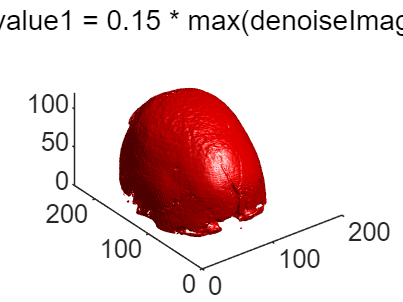

% This is a 4D dataset, so we have to squeeze it into 3D data
volume3D = squeeze(dicomVolume4D);

% Apply a noise reduction filter
% here we use a median filter which can retain the edge information
denoiseImage=medfilt3(volume3D,[3,3,3]);

% Select an isovalue for isosurface extraction
isovalue1 = 0.15 * max(denoiseImage(:)); 
isovalue2 = min(denoiseImage(:)); 
isovalue3 = max(denoiseImage(:)); 
isovalue4 = 0.5*max(denoiseImage(:)); 



%%%%%% Extract isosurface
[f1, v1] = isosurface(denoiseImage, isovalue1);
[f2, v2] = isosurface(denoiseImage, isovalue2);
[f3, v3] = isosurface(denoiseImage, isovalue3);
[f4, v4] = isosurface(denoiseImage, isovalue4);
% use Face-vertex meshes to store polygon meshes to realize  surface rendering 
% isosurface contains the Marching Cubes algorithm to create a polygonal mesh representing the isosurface.

% Create a figure and plot the isosurface
figure;
p1 = patch('Faces', f1, 'Vertices', v1);
% The patch function is used for creating polygonal patches in 3D space. 
% defining a set of polygons by their vertices (V) and the faces (F) that connect these vertices.
p1.FaceColor = 'red';
p1.EdgeColor = 'none';
daspect([1,1,1])
view(3); % Set the view to 3D
camlight; lighting gouraud
title("isovalue1 = 0.15 * max(denoiseImage(:))")

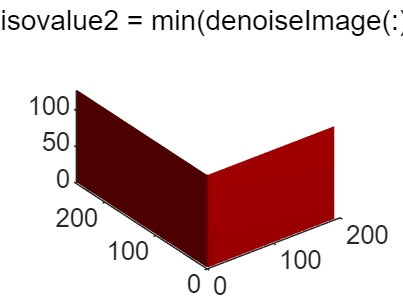


figure;
p2 = patch('Faces', f2, 'Vertices', v2);
% The patch function is used for creating polygonal patches in 3D space. 
% defining a set of polygons by their vertices (V) and the faces (F) that connect these vertices.
p2.FaceColor = 'red';
p2.EdgeColor = 'none';
daspect([1,1,1])
view(3); % Set the view to 3D
camlight; lighting gouraud
title("isovalue2 = min(denoiseImage(:))")

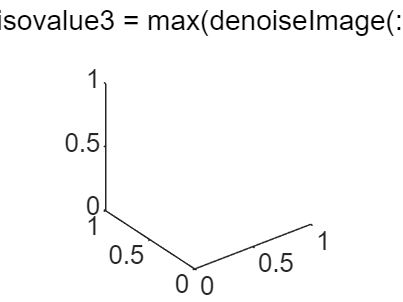


figure;
p3 = patch('Faces', f3, 'Vertices', v3);
% The patch function is used for creating polygonal patches in 3D space. 
% defining a set of polygons by their vertices (V) and the faces (F) that connect these vertices.
p3.FaceColor = 'red';
p3.EdgeColor = 'none';
daspect([1,1,1])
view(3); % Set the view to 3D
camlight; lighting gouraud
title("isovalue3 = max(denoiseImage(:))")

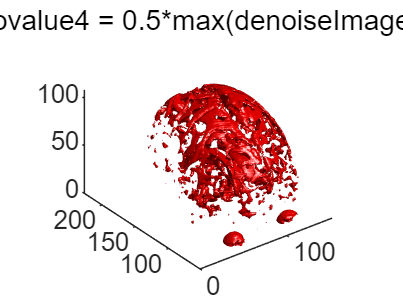


figure;
p4 = patch('Faces', f4, 'Vertices', v4);
% The patch function is used for creating polygonal patches in 3D space. 
% defining a set of polygons by their vertices (V) and the faces (F) that connect these vertices.
p4.FaceColor = 'red';
p4.EdgeColor = 'none';
daspect([1,1,1])
view(3); % Set the view to 3D
camlight; lighting gouraud
title("isovalue4 = 0.5*max(denoiseImage(:))")


%%%%% cloudpoint

% Choose a threshold
threshold1 = 0.15 * max(volume3D(:));
threshold2 = min(volume3D(:));
threshold3 = max(volume3D(:));
threshold4 = 0.51 * max(volume3D(:));

% Find points above the threshold
pointsIdx1 = find(volume3D > threshold1);
pointsIdx2 = find(volume3D > threshold2);
pointsIdx3 = find(volume3D > threshold3);
pointsIdx4 = find(volume3D > threshold4);

% Convert indices to subscripted coordinates
[x1, y1, z1] = ind2sub(size(volume3D), pointsIdx1);
[x2, y2, z2] = ind2sub(size(volume3D), pointsIdx2);
[x3, y3, z3] = ind2sub(size(volume3D), pointsIdx3);
[x4, y4, z4] = ind2sub(size(volume3D), pointsIdx4);


% Create the point cloud
ptCloud1 = pointCloud([x1, y1, z1]);
ptCloud2 = pointCloud([x2, y2, z2]);
ptCloud3 = pointCloud([x3, y3, z3]);
ptCloud4 = pointCloud([x4, y4, z4]);

% Visualize the point cloud
figure;
pcshow(ptCloud1);

pcshow 需要 Computer Vision Toolbox。

title("threshold1 = 0.15 * max(volume3D(:))")

figure;
pcshow(ptCloud2);
title("threshold2 = min(volume3D(:))")

figure;
pcshow(ptCloud3);
title("threshold3 = max(volume3D(:))")

figure;
pcshow(ptCloud4);
title("threshold4 = 0.51 * max(volume3D(:))")


%%%%%%%% volume rendering


% normalize the intensity values of the image data to a standard range [0,1]
volume3D = rescale(volume3D);

% Create a colormap with three color channels
colormap = [linspace(0, 1, 256)', zeros(256, 2)]; % Red gradient; render higher intensity values in red; other two channels are set zero
% The alpha map, which controls transparency, has been set to make lower intensity values more transparent

% Define an alpha map for transparency; square: making lower intensities more transparent
alphaMap = linspace(0, 1, 256).^2; % Quadratic scale for alpha values

% Perform volume rendering with former settings

h = volshow(volume3D, 'Colormap', colormap, 'Alphamap', alphaMap);% volshow renders the 3D volume using the specified colormap and alpha map.

% Adjust the view settings and axis
view(3); % Standard 3D view
axis tight; % Fit the axes tightly to the volume
daspect([1 1 1]); % Equal aspect ratio for all axes
camlight; lighting gouraud








